gunzip('https://github.com/sp-au-mu-nl/SpeechComm/raw/refs/heads/main/data/chap04.zip','data')

unzip('data/chap04.zip', 'data/chap04/')

プログラム 4.2

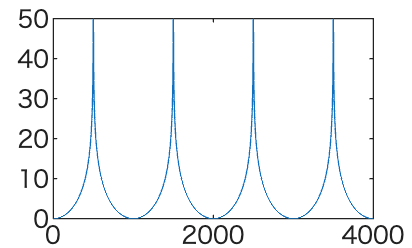

c = 340; lengthV = 0.17; fs = 8000;
frequency = 0:fs/2;
plot(frequency, 20*log10(abs(1./cos(2*pi*frequency*lengthV/c))));
ylim([0 50])

プログラム 4.3

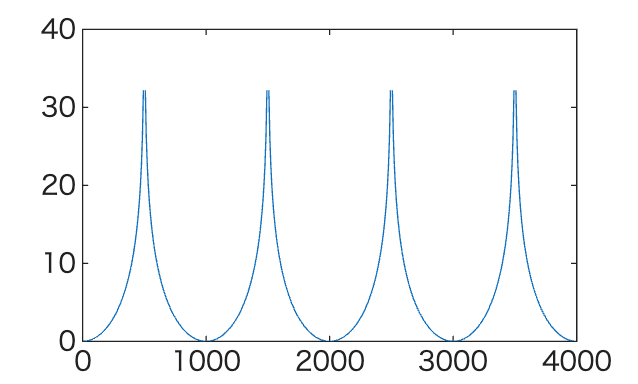

sr = 8000;
b(5) = 2;
a(1) = 1; a(9) = 1;
[H, w] = freqz(b, a);
f = sr*w/(2*pi);
plot(f, 20*log10(abs(H)))

プログラム 4.9 (章末問題 3)

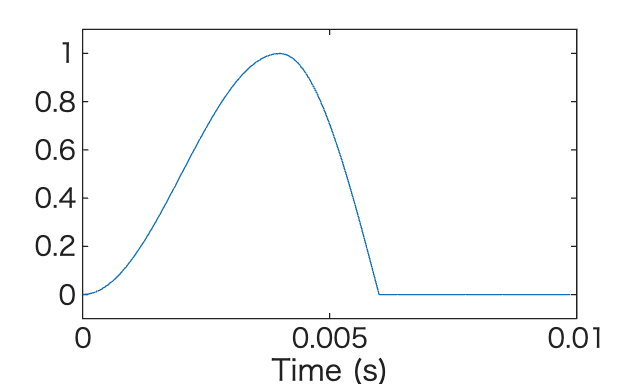

sr = 8000;
T1 = 0.004; T2 = 0.002;
t1 = 0:1/sr:T1-1/sr;
g1 = 0.5*(1-cos(2*pi*t1/2/T1));
t2 = T1:1/sr:T1+T2-1/sr;
g2 = cos(2*pi*(t2-T1)/4/T2);
t3 = T1+T2:1/sr:0.01-1/sr;
g3 = zeros(size(t3));
g = [g1 g2 g3]; % Combine the generated waveforms
t = [t1 t2 t3]; % Create a time vector for the combined signal
plot(t, g); % Plot the combined waveform
xlim([0 0.01]);
ylim([-.1 1.1])
xlabel('Time (s)');